clear all;
clf;

## Quadcopter parameters and physical constants

global g quad_mass_kg black_mass_kg white_mass_kg thrust_data_kgf theta_deg dyn_friction_coeff cart_height_m thrust_centerline_distance_m k1_m k2_m k3_m k4_m
g = 9.81;
quad_mass_kg = 0.5; % mass of arm structures + ESC + motors !!(NEEDS TO CHANGE, PROVIDED BY STRUCTURES)!!
black_mass_kg = 0.06924; % mass of black mounting plate
white_mass_kg = 0.08076; % mass of white plates (plates interacting with lidar sensor)

thrust_data_kgf = xlsread('motorspecs.xlsx');

k1_m = 0.01; % CoG of the quadcopter except the cable
k2_m = 24E-3; % Attachment point of the cable
k3_m = 0.012; % CoG of black mounting plate
k4_m = 0.012; % CoG of white plates (plates interacting with lidar sensor)

theta_deg = 0; % thrust tilt angle !!(NEEDS TO CHANGE, PROVIDED BY STRUCTURES)!!
dyn_friction_coeff = 0.14;
cart_height_m = 0.2104

cart_height_m = 0.2104

thrust_centerline_distance_m = 0.01; % TODO: CHANGE!

max_y_m = 1.44;

## Controller and path

% Waypoints as timeseries (format is (y_location, time))
waypoints = timeseries([0, 10, 100, 15, 48, 14]', [0, 5, 8, 13, 15, 19]);
load('samplemission_edited.mat')
%assert(checkTrack(waypoints), 'Track is impossible to do due to acceleration limits');

controller = ControlSystem([0.8, 0.18, 0.19], waypoints)

controller =   ControlSystem with properties:

               gains: [0.8000 0.1800 0.1900]
           waypoints: [1×1 timeseries]
    cur_waypoint_idx: 1
              y_prev: -1
              t_prev: -1
           firstIter: 1
           err_accum: 0
            err_prev: 0
                logs: []


## Simulation parameters

T_max = max(waypoints.Time);
dt = 1E-3;

% Initial position and acceleration
y0 = 0;
v0 = 0;

## Simulation loop

y = y0;
v = v0;

t_arr = 0:dt:T_max;

logs.t = t_arr;
logs.y = zeros(numel(t_arr), 1);
logs.v = zeros(numel(t_arr), 1);
logs.thrust = zeros(numel(t_arr), 1);

for t_idx = 1:numel(t_arr)
    t = t_arr(t_idx);
    
    thrust = controller.calculate(y, t);
    accel = accelerationFunction(thrust, y, v);
    
    y = y + v*dt;
    v = v + accel*dt;
    
    % Make sure to not fall through the floor
    if y <= 0
        y = 0;
        v = max(0, v); % make sure v is not negative
    end
    
    if y >= max_y_m
        y = max_y_m;
        v = min(0, v); % make sure v is only negative
    end
    
    
    logs.y(t_idx) = y;
    logs.v(t_idx) = v;
    logs.thrust(t_idx) = thrust;
end

## Plotting

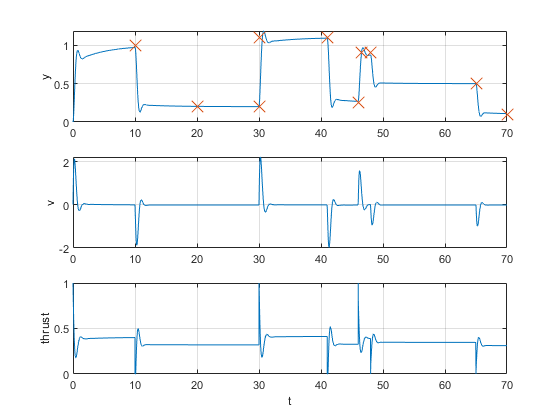

figure;

subplot(3, 1, 1);
plot(logs.t, logs.y);
grid on;
hold on;
scatter(waypoints.Time, waypoints.Data, 150, 'x');
ylabel('y')
hold off;

subplot(3, 1, 2);
plot(logs.t, logs.v);
grid on;
ylabel('v')

subplot(3, 1, 3);
plot(logs.t, logs.thrust);
grid on;
ylabel('thrust')
xlabel('t')


disp(calcAccuracy(logs, waypoints));

    0.1163



function accel = accelerationFunction(thrust, y, v) % Calculates acceleration in kgms^-2, +ve up

    global g quad_mass_kg black_mass_kg white_mass_kg thrust_data_kgf theta_deg dyn_friction_coeff cart_height_m thrust_centerline_distance_m k1_m k2_m k3_m k4_m;
    Fit_thrust = fit(thrust_data_kgf(:,1), thrust_data_kgf(:,2), 'smoothingspline');
    thrust_term = Fit_thrust(max(min(thrust, 1), 0)*100)*g*cosd(theta_deg);
    cable_mass_kg = 0.19*(y + 0.5648);
    
    total_mass_kg = quad_mass_kg + cable_mass_kg + black_mass_kg + white_mass_kg;
    grav_term = -(quad_mass_kg + cable_mass_kg + black_mass_kg + white_mass_kg)*g;
    total_weight_moment = -quad_mass_kg*g*k1_m - cable_mass_kg*g*k2_m - black_mass_kg*g*k3_m - white_mass_kg*g*k4_m;
    
    if v == 0
        % TODO: Static friciton model
        resultant = thrust_term + grav_term;
        static_friction = 0.13*g;
        if abs(resultant) < static_friction
            accel = 0;
            return;
        else
            friction_term = -sign(resultant)*static_friction;
        end
    else
        ff1 = abs(dyn_friction_coeff*(thrust_term*thrust_centerline_distance_m*cosd(theta_deg) + total_weight_moment)/cart_height_m);
        ff2 = abs(dyn_friction_coeff*(thrust_term*(cart_height_m*tand(theta_deg) - thrust_centerline_distance_m)*cosd(theta_deg) - total_weight_moment)/cart_height_m);
        
        
        friction_term = -(ff1 + ff2)*sign(v);       
    end
    
    accel = (thrust_term + grav_term + friction_term) / total_mass_kg;
end

function rms_accuracy = calcAccuracy(logs, waypoints)
    [~, time_indices] = min(abs(logs.t - waypoints.Time), [], 2);
    prev_idx = 1;
    err = 0;
    
    for idx_num = 1:numel(time_indices)
        idx = time_indices(idx_num);
        err = err + sum((logs.y(prev_idx:idx) - waypoints.Data(idx_num)).^2);
        prev_idx = idx;
    end
    
    %accuracies = waypoints.Data - logs.y(time_indices)
    %accuracy = logs.y - waypoints.Data
    %rms_accuracy = sqrt(mean(accuracies.^2));
    rms_accuracy = sqrt(err/numel(logs.t));
end

function trackWorks = checkTrack(waypoints)
    % Check if the max acceleration is lower than max thrust and min
    % deceleration is not smaller than g
    global g quad_mass_kg max_thrust_N;
    trackWorks = true;
    for idx = 2:numel(waypoints.Time)
        delta_s = waypoints.Data(idx) - waypoints.Data(idx - 1);
        delta_t = waypoints.Time(idx) - waypoints.Time(idx - 1);
        
        acc = 2*delta_s/delta_t^2;
        
        if acc < -g || acc > max_thrust_N/quad_mass_kg - g
            trackWorks = false;
            return;
        end
    end
end